# Desarrollo Laboratorio 3 - Robótica 2021-II

### Edgar Alejandro Ruíz Velasco

### Jesus Daniel Caballero Colina

### Jhohan David Contreras Aragón

**Para este equipo de trabajo se asignó el robot industrial *****Epson C4***

### Parte 1 Ruta:

El presente equipo de trabajo es el no. 6, por ende el plano vector asignado es $\left\lbrack 0,1,1\right\rbrack$. Además se seleccionó la ruta:

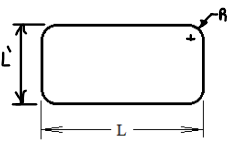

Donde L corresponde a 0.4 del alcance horizontal máximo del robot. Según el manual del robot C4 (investigación realizada en taller 1) el alcance horizontal máximo es de 665 mm, es decir que $L=0\ldotp 4\;\left(665\textrm{mm}\right)=266\textrm{mm}$. La otra dimensión del rectangulo se va a tomar como $L^{\prime } =0\ldotp 5L=133\textrm{mm}$ y el radio de cada esquina se va a tomar como $R=20\textrm{mm}$. Por último, el centro del rectangulo de la pista se posicionó $\left\lbrack x,y,z\right\rbrack =\left\lbrack 0,415,570\right\rbrack$ (posición de calibración del robot).

Ahora se hallan los puntos de la ruta, siguiendo las dimensiones delimitadas anteriormente, en el plano XY y centrado en la posición de calibración del robot:

% Dimensiones y posición de ruta
P_centro = [0,415,570];
L = 266;
L1 = 133;
R = 20;
% Especificación de ruta
n = 200; %Número de viapoints

%--------------------------------------------
Perimetro = (L-2*R)*2 + (L1-2*R)*2 + 2*pi*R;
d = Perimetro / n; % Distancia entre puntos

viapoints = zeros(n,3);
% El primero punto se escoge en la posición superior central del rectangulo
i = 1;
x = 0;
while (x < L/2-R)
    viapoints(i,1:3) = [x,L1/2,0]+P_centro;
    x = x + d;
    i = i + 1;
end
d1 = x - (L/2-R);
theta1 = d1/R;
theta2 = d/R;

theta = theta1;
while theta < pi/2
    viapoints(i,1:3) = [sin(theta),cos(theta),0]*R+[L/2-R,L1/2-R,0]+P_centro;
    theta = theta + theta2;
    i = i + 1;
end
d1 = (theta2-(theta-pi/2))*R;
d2 = d - d1;

y = L1/2 - R - d2;
while y > R - L1/2
    viapoints(i,1:3) = [L/2,y,0]+P_centro;
    y = y - d;
    i = i + 1;
end
d1 = (R - L1/2) - y;
theta1 = d1/R;
theta2 = d/R;

theta = pi/2 + theta1;
while theta < pi
    viapoints(i,1:3) = [sin(theta),cos(theta),0]*R+[L/2-R,-L1/2+R,0]+P_centro;
    theta = theta + theta2;
    i = i + 1;
end
d1 = (theta2-(theta-pi))*R;
d2 = d - d1;

x = L/2 - R - d2;
while x > R - L/2
    viapoints(i,1:3) = [x,-L1/2,0]+P_centro;
    x = x - d;
    i = i + 1;
end
d1 = (R - L/2) - x;
theta1 = d1/R;
theta2 = d/R;

theta = pi + theta1;
while theta < 3*pi/2
    viapoints(i,1:3) = [sin(theta),cos(theta),0]*R+[-L/2+R,-L1/2+R,0]+P_centro;
    theta = theta + theta2;
    i = i + 1;
end
d1 = (theta2-(theta-3*pi/2))*R;
d2 = d - d1;

y = - L1/2 + R + d2;
while y < L1/2 - R
    viapoints(i,1:3) = [-L/2,y,0]+P_centro;
    y = y + d;
    i = i + 1;
end
d1 = y - (L1/2 - R);
theta1 = d1/R;
theta2 = d/R;

theta = 3*pi/2 + theta1;
while theta < 2*pi
    viapoints(i,1:3) = [sin(theta),cos(theta),0]*R+[-L/2+R,L1/2-R,0]+P_centro;
    theta = theta + theta2;
    i = i + 1;
end
d1 = (theta2-(theta-2*pi))*R;
d2 = d - d1;

x = -L/2 + R + d2;
while x < 0
    viapoints(i,1:3) = [x,L1/2,0]+P_centro;
    x = x + d;
    i = i + 1;
end

close all
figure("Name","Ruta")
hold on
for j = 1:n
   plot3(viapoints(j,1),viapoints(j,2),viapoints(j,3),'b.','MarkerSize',10);
end
xlim([-133 133])
ylim([348 482])

Teniendo los puntos en el plano XY se procede a rotar cada uno de tal manera que queden en el plano vector $\left\lbrack 0,1,1\right\rbrack$.

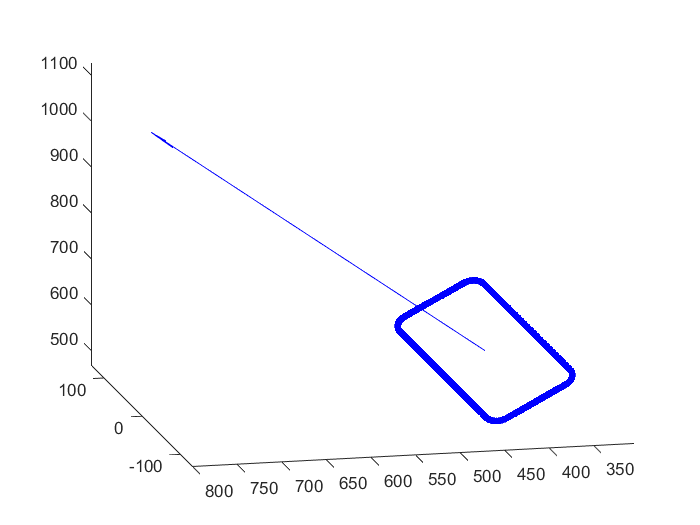

MTH = rotx(-pi/4);
for i = 1:n
    viapoints(i,1:3) = (MTH*(viapoints(i,1:3)-P_centro)')'+P_centro;
end

close all
figure("Name","Ruta")
hold on
for j = 1:n
   plot3(viapoints(j,1),viapoints(j,2),viapoints(j,3),'b.','MarkerSize',10);
end
quiver3(P_centro(1),P_centro(2),P_centro(3),P_centro(1),P_centro(2)+1,P_centro(3)+1,'blue')

xlim([-133 133])
ylim([305 800])
zlim([467 1127])
view([-103 19])

### Parte 2 Modelo diferencial de primer Orden:

Considerando que para que el robot ejecute los movimientos, se desea establecer una relacion entre las velocidades del efector final y las articulaciones.

1. Con los valores numericos de longitudes y desplazamientos de los eslabones del robot asignado obtenga el Jacobiano (como una matriz de valores numericos, NO simbolico) en funcion de los angulos de articulacion. 

T6b = trotx(pi)*transl([0 0 6.5]);
T6b=[1 0 0 0; 0 -1 0 0; 0 0 -1 -6.5; 0 0 0 1];

%     MDHm(thetai,      di,    ai-1,  alpha-1,   sigma, offset)
Links(1) = Link('revolute','alpha',0,    'a',0, 'd',32, 'offset',0,'modified', 'qlim',[-17*pi/18 17*pi/18]);
Links(2) = Link('revolute','alpha',pi/2, 'a',10,'d',0,  'offset',pi/2,'modified', 'qlim',[-8*pi/9 13*pi/36]);
Links(3) = Link('revolute','alpha',0,    'a',25,'d',0,  'offset',0,   'modified', 'qlim',[-17*pi/60 5*pi/4]);
Links(4) = Link('revolute','alpha',-pi/2,'a',0, 'd',-25,'offset',0,   'modified', 'qlim',[-10*pi/9 10*pi/9]);
Links(5) = Link('revolute','alpha',pi/2, 'a',0, 'd',0,  'offset',0,   'modified', 'qlim',[-3*pi/4 3*pi/4]);
Links(6) = Link('revolute','alpha',-pi/2,'a',0, 'd',0,  'offset',0,   'modified', 'qlim',[-2*pi 2*pi]);

Epson_C4 = SerialLink(Links,'name','Epson C4','tool',T6b)

 
Epson_C4 = 
 
Epson C4 (6 axis, RRRRRR, modDH, fastRNE)                                     
                                                                              
+---+-----------+-----------+-----------+-----------+-----------+             
| j |     theta |         d |         a |     alpha |    offset |             
+---+-----------+-----------+-----------+-----------+-----------+             
|  1|         q1|         32|          0|          0|          0|             
|  2|         q2|          0|         10|      1.571|      1.571|             
|  3|         q3|          0|         25|          0|          0|             
|  4|         q4|        -25|          0|     -1.571|          0|             
|  5|         q5|          0|          0|      1.571|          0|             
|  6|         q6|          0|          0|     -1.571|          0|             
+---+-----------+-----------+-----------+-----------+-----------+             
                                    


syms q1 q2 q3 q4 q5 q6
%Matrices MTH
T01 = Epson_C4.A(1, [q1 q2 q3 q4 q5 q6]);
T12 = Epson_C4.A(2, [q1 q2 q3 q4 q5 q6]);
T23 = Epson_C4.A(3, [q1 q2 q3 q4 q5 q6]);
T34 = Epson_C4.A(4, [q1 q2 q3 q4 q5 q6]);
T45 = Epson_C4.A(5, [q1 q2 q3 q4 q5 q6]);
T56 = Epson_C4.A(6, [q1 q2 q3 q4 q5 q6]);
T_6_tool = Epson_C4.tool;

A01 = simplify(T01);
A02 = simplify(A01*T12);
A03 = simplify(A02*T23);
A04 = simplify(A03*T23);
A05 = simplify(A04*T23);
A06 = simplify(A05*T23);
A0NOA = A06*T_6_tool;

% Calculos de 0Zi
z01 = A01(1:3,3); %art 1
z02 = A02(1:3,3); %art 2
z03 = A03(1:3,3); %art 3
z04 = A04(1:3,3); %art 4
z05 = A05(1:3,3); %art 5
z06 = A06(1:3,3); %art 6

%Vectores Pi
p6NOA=A0NOA(1:3,4)-A06(1:3,4);
p5NOA=A0NOA(1:3,4)-A05(1:3,4);
p4NOA=A0NOA(1:3,4)-A04(1:3,4);
p3NOA=A0NOA(1:3,4)-A03(1:3,4);
p2NOA=A0NOA(1:3,4)-A02(1:3,4);
p1NOA=A0NOA(1:3,4)-A01(1:3,4);

%Jacobianos
J1=[(skew(z01)*p1NOA); z01]; %Rotacional
J2=[(skew(z02)*p2NOA); z02]; %Rotacional
J3=[(skew(z03)*p3NOA); z03]; %Rotacional
J4=[(skew(z04)*p4NOA); z04]; %Rotacional
J5=[(skew(z05)*p5NOA); z05]; %Rotacional
J6=[(skew(z06)*p6NOA); z06]; %Rotacional
Jacobiano=([J1,J2,J3,J4,J5,J6]); %% Matriz jacobiana a manera simbólica en función de q1,q2,q3,q4,q5 

Postura de home.

target=Epson_C4.fkine([0 0 0 0 0 0])

target =     0.0000    0.0000    1.0000   41.5000
    0.0000   -1.0000    0.0000    0.0000
    1.0000    0.0000   -0.0000   57.0000
         0         0         0    1.0000


syms q1 q2 q3 q4 q5 q6 real
A_0_1=Links(1).A(q1);
A_1_2=Links(2).A(q2);
A_2_3=Links(3).A(q3);
A_3_4=Links(4).A(q4);
A_4_5=Links(5).A(q5);
A_5_6=Links(6).A(q6);
A_6_NOA=trotx(pi)*transl([0 0 6.5]);

T_0_6=A_0_1*A_1_2*A_2_3*A_3_4*A_4_5*A_5_6;
% figure("Name","RVC")
% hold on
% %trplot(eye(4), 'width',0.75,'frame','0','arrow')
% Epson_C4.plot([0 0 0 0 0 0],'workspace',[-70 70 -70 70 0 90],'noa','jaxes','view',[-160 40])
% axis([-70 70 -70 70 0 90])
% Epson_C4.teach()


qS=Epson_C4.ikunc(target)*180/pi

qS =      0     0     0     0     0     0


q1=qS(1);
q2=qS(2);
q3=qS(3);
q4=qS(4);
q5=qS(5);
q6=qS(6);
Je=eval(Jacobiano) % Matriz jacobiana de valores numéricos para q=[0,1,-0.5,2,1,0.5]

Je =    -6.5000 -100.0000  -75.0000  -50.0000  -25.0000         0
   10.0000         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0   -1.0000   -1.0000   -1.0000   -1.0000   -1.0000
    1.0000    0.0000    0.0000    0.0000    0.0000    0.0000


q_p=inv(Je'*Je)*Je'*[10.0 20.0 5.0 5 10 -5]'

q_p =     1.9307
    1.5946
    0.4075
    1.8122
   -3.3792
   -7.7567
